# Train A KNN Model

## Problem 1

In this task, you will utilize the Spotify API to gather data on songs by Kendrick Lamar and Sabrina Carpenter. The API will provide essential features such as song duration and popularity score for each track. **Please do not delete or modify the first or third text box as they import crucial data from the Spotify API and execute a function to save it in an Excel file**. Once the data is collected, your objective is to build a machine learning model that predicts whether a given song belongs to Kendrick Lamar or Sabrina Carpenter based on its duration and popularity. To achieve this, you will select song duration and popularity score as the features for classification, considering their potential to capture distinct characteristics of each artist's songs.

You will train a machine learning model using the training data, employing algorithms such as logistic regression, decision trees, or random forests (Hint: Use the KNN model from the lesson). The model will utilize song duration and popularity score as input features to make predictions. Once trained, you will evaluate the model's performance on the testing data, employing metrics such as accuracy and precision to assess its effectiveness (remember to include a confusion matrix).

### Step 1: Access Spotify API

**The first coding cell (only change the ID and Secret):**

clc;clear;

% Set your client ID and client secret
clientID = 'your ID goes here'; % Replace with your actual client ID
clientSecret = 'your Secret goes here'; % Replace with your actual client secret

% Create the URL for token retrieval
url = 'https://accounts.spotify.com/api/token';

% Encode the client ID and client secret in base64
authString = matlab.net.base64encode([clientID ':' clientSecret]);

% Set the options for the HTTP request
options = weboptions('RequestMethod', 'post', 'MediaType', 'application/x-www-form-urlencoded', ...
    'HeaderFields', {'Authorization', ['Basic ' authString]});

% Set the POST data
postData = 'grant_type=client_credentials';

% Make the POST request to retrieve the access token
response = webwrite(url, postData, options);

% Extract the access token from the response
Token = response.access_token;

% Display the access token (you can process it further as needed)
disp(['Access Token: ' Token]);

Access Token: BQABw8t5ZbzNOJHqvHhUtMRNDBdXEqIt6Qu04TKC3fYLZYOr9RMvG2nnkJiWdBp0OpJy1dPlILHMvXZsXGRGxSxCFyBJ3TGTxjQQqCScKvhaz7zItac



% Define album sets
albumIDsSet1 = {'6PBZN8cbwkqm1ERj2BGXJ1', '7iOAJaGBmk67o337zaqt0R'};  % Replace with actual album IDs
albumIDsSet2 = {'79ONNoS4M9tfIA1mYLBYVX', '5kDmlA2g9Y1YCbNo2Ufxlz'};  % Replace with actual album IDs

% Fetch album details and write to separate Excel files
fetchAlbumDetailsAndWriteToExcel(albumIDsSet1, 'SongTestData.xlsx', Token);

Data written to Excel file: SongTestData.xlsx


fetchAlbumDetailsAndWriteToExcel(albumIDsSet2, 'VerificationTestData2.xlsx', Token);

Data written to Excel file: VerificationTestData2.xlsx


### Step 2: Read & Plot the Data

**Where you need to add your code:**

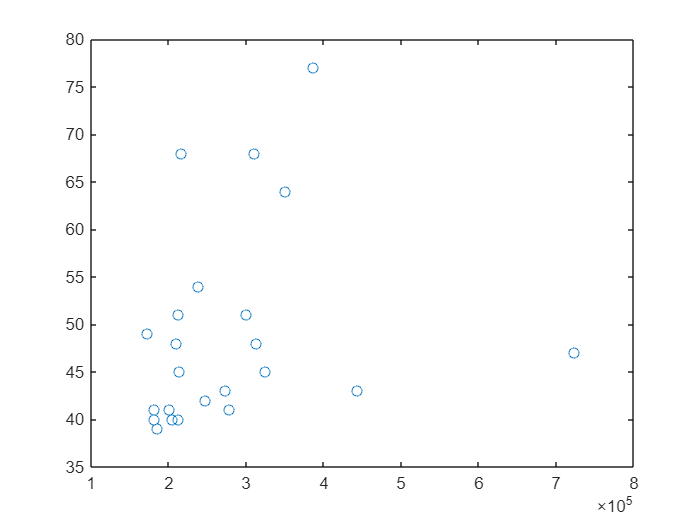

% Read the data from the Excel file into a table
SongTestData = readtable("SongTestData.xlsx");

% Extract durations and popularity data from the table
x = SongTestData.durations;
y = SongTestData.popularity;

% Plot the durations vs. popularity data
plot(x, y, 'o')

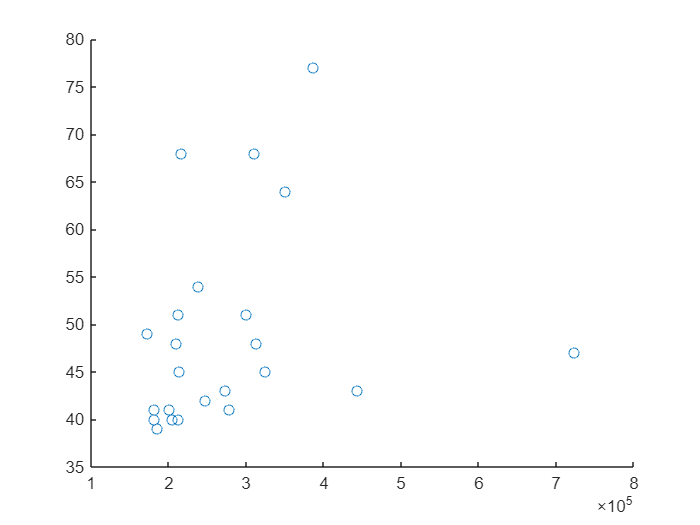


% Scatter plot of durations vs. popularity
scatter(SongTestData.durations, SongTestData.popularity)

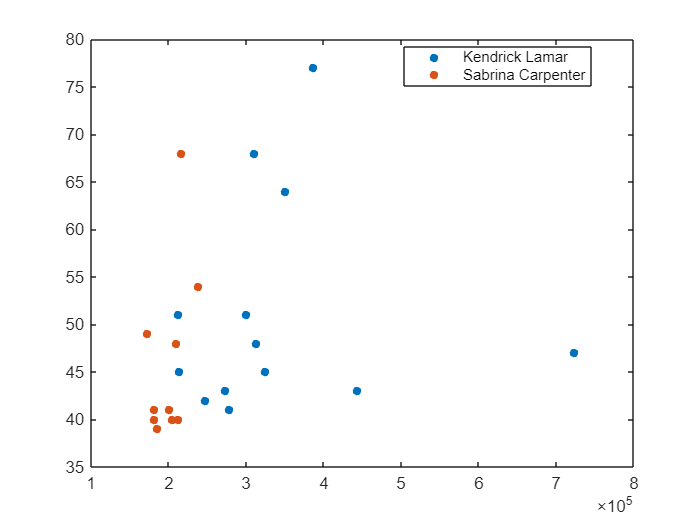


% Grouped scatter plot of durations vs. popularity, color-coded by artists
gscatter(SongTestData.durations, SongTestData.popularity, SongTestData.artists)

### Step 3: Fit the Model

**Where you need to add your code:**

% Fit a k-nearest neighbors (KNN) classification model using the data
% and save in the variable knnmodel. 
% Predict the artist based on durations and popularity and store in
% the variable predicted. 
knnmodel = fitcknn(SongTestData, "artists", "NumNeighbors", 8);
predicted = predict(knnmodel, [2*10^5, 40]);

% Read the verification data from the Excel file into a table
VerificationTestData2 = readtable('VerificationTestData2.xlsx');

% Use the trained KNN model to predict the artists for the verification data
predictions = predict(knnmodel, VerificationTestData2);

% Check if the predictions are correct and calculate accuracy
iscorrect = cellfun(@isequal, predictions, VerificationTestData2.artists);
accuracy = sum(iscorrect) / numel(predictions)

accuracy = 0.6562


% Calculate misclassification rate
iswrong = ~cellfun(@isequal, predictions, VerificationTestData2.artists);
misclassrate = sum(iswrong) / numel(predictions)

misclassrate = 0.3438

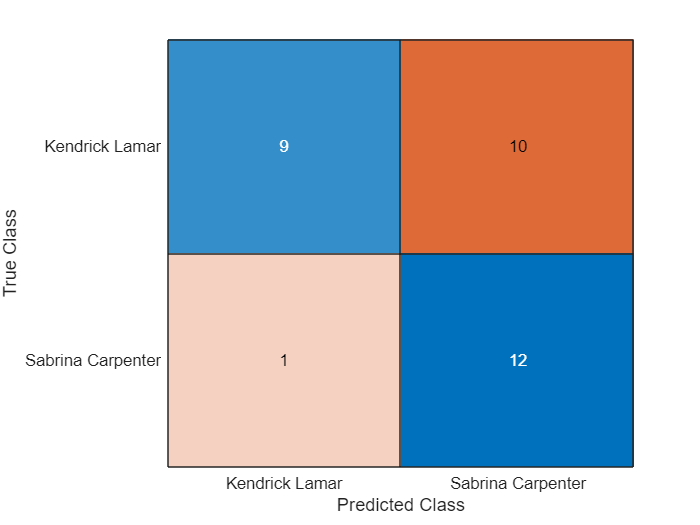


% Generate a confusion chart to visualize the performance of the classifier
confusionchart(VerificationTestData2.artists, predictions);

Third cell (function):

function fetchAlbumDetailsAndWriteToExcel(albumIDs, excelFileName, Token)
    % Initialize arrays to store song details
    artists = {};
    durations = [];
    popularity = [];
    
    % Loop over each album ID
    for i = 1:length(albumIDs)
        % Construct the URL for getting the tracks of the album
        url = ['https://api.spotify.com/v1/albums/', albumIDs{i}, '/tracks'];
        
        % Set up the web options with the access token
        options = weboptions('HeaderFields', {'Authorization', ['Bearer ', Token]});
        
        try
            % Make the GET request to retrieve tracks of the album
            response = webread(url, options);
            
            % Check if the response contains track information
            if isfield(response, 'items')
                tracks = response.items;
                % For each track, make another request to get full track details (including popularity)
                for j = 1:length(tracks)
                    trackID = tracks(j).id;
                    trackURL = ['https://api.spotify.com/v1/tracks/', trackID];
                    trackDetails = webread(trackURL, options);
                    
                    % Check if trackDetails has all necessary fields
                    if isfield(trackDetails, 'duration_ms') && isfield(trackDetails, 'popularity') && isfield(trackDetails, 'artists')
                        % Check if the artist is "Kendrick Lamar" or "Sabrina Carpenter"
                        for k = 1:length(trackDetails.artists)
                            if strcmpi(trackDetails.artists(k).name, 'Kendrick Lamar') || strcmpi(trackDetails.artists(k).name, 'Sabrina Carpenter')
                                % Store artist name, duration, and popularity in arrays
                                artists = [artists; trackDetails.artists(k).name];
                                durations = [durations; trackDetails.duration_ms];
                                popularity = [popularity; trackDetails.popularity];
                                break; % Break the loop if the artist is found
                            end
                        end
                    else
                        disp(['Track details missing for track ID: ', trackID]);
                    end
                end
            else
                disp(['Response does not contain track information for album ID: ', albumIDs{i}]);
            end
        catch ME
            % Handle HTTP errors gracefully
            if contains(ME.message, '404')
                disp(['Error 404: Album ID not found - ', albumIDs{i}]);
            else
                disp(['Error retrieving data for album ID: ', albumIDs{i}]);
                disp(ME.message);
            end
        end
    end
    
    % Create a table from the arrays
    if ~isempty(artists)
        allSongDetails = table(artists, durations, popularity);
        
        % Write data to Excel file
        writetable(allSongDetails, excelFileName);
        disp(['Data written to Excel file: ', excelFileName]);
    else
        disp('No valid track information retrieved for Kendrick Lamar or Sabrina Carpenter.');
    end
end
 

Testing the function:

filepath = 'SongTestData.xlsx';
fetchAlbumDetailsAndWriteToExcel({'6PBZN8cbwkqm1ERj2BGXJ1'}, filepath, Token);

Data written to Excel file: SongTestData.xlsx
